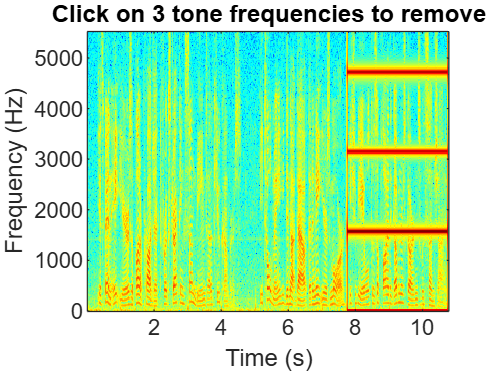

% === Step 1: Read the audio ===
[xx, fs] = audioread('SunshineSquare.wav');
xx = xx(:);  % Ensure column vector

% === Step 2: Show spectrogram and (optionally) select tones ===
figure;
specgram(xx, 512, fs);
title('Click on 3 tone frequencies to remove');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

fs = 11025


A = -1.246980


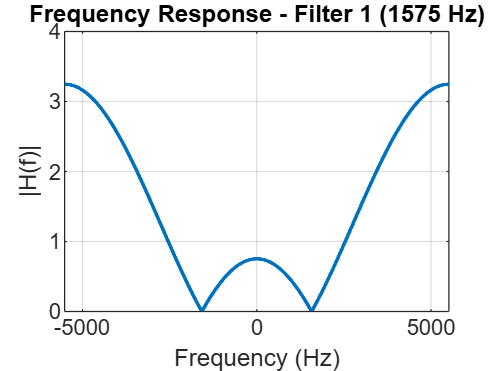

fs = 11025


A = 0.445042


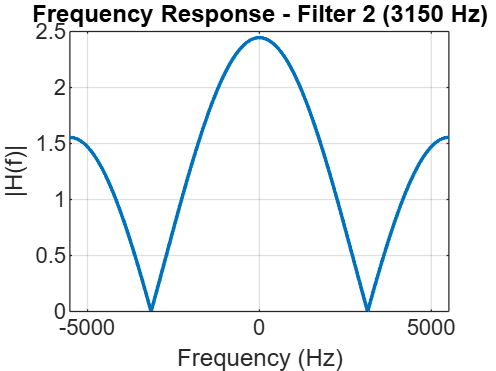

fs = 11025


A = 1.801938


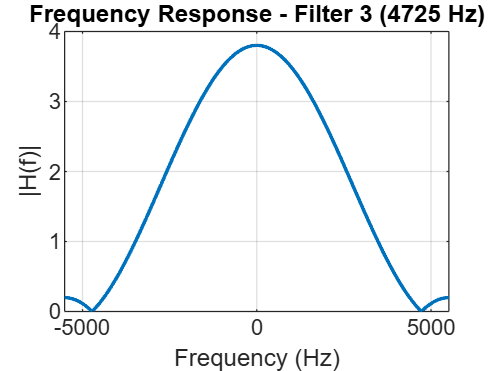


% If you want manual input via mouse, uncomment below:
% [~, y] = ginput(3);
% f_tones = round(y(:));
% disp('Selected tone frequencies (Hz):');
% disp(f_tones');

% === Step 3: Design 3-point notch filters and apply ===
xx_filtered = xx;
f_tones = [1575, 3150, 4725];

for i = 1:length(f_tones)
    f = f_tones(i);
    fprintf("fs = %d\n", fs);
    
    omega_hat = 2 * pi * f / fs;        % Normalized angular frequency
    A = -2 * cos(omega_hat);            % Middle coefficient for FIR notch
    fprintf("A = %f\n", A);
    
    hh = [1, A, 1];                     % 3-tap FIR filter
    xx_filtered = filter(hh, 1, xx_filtered);  % Apply filter

    % Plot frequency response (from -fs/2 to fs/2)
    figure;
    w = linspace(-pi, pi, 1024);
    H = freqz(hh, 1, w);
    f_axis = w / (2*pi) * fs;
    
    plot(f_axis, abs(H), 'LineWidth', 1.5);
    grid on;
    title(['Frequency Response - Filter ', num2str(i), ' (', num2str(f), ' Hz)']);
    xlabel('Frequency (Hz)');
    ylabel('|H(f)|');
    xlim([-fs/2, fs/2]);
end


% === Step 4: Save filtered audio ===
audiowrite('Filtered_Sunshine_ginput.wav', xx_filtered, fs);

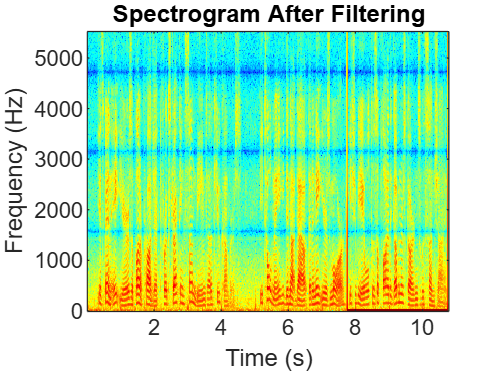


% === Step 5: Plot spectrogram of filtered signal ===
figure;
specgram(xx_filtered, 512, fs);
title('Spectrogram After Filtering');
xlabel('Time (s)');
ylabel('Frequency (Hz)');


% === Play audio (optional) ===
sound(xx_filtered, fs);

% === Done ===
disp('Filtering complete. Saved as Filtered_Sunshine_ginput.wav');

Filtering complete. Saved as Filtered_Sunshine_ginput.wav
